x0 = [3;150;2]

x0 =      3
   150
     2


t = linspace(0,4,200)

t =          0    0.0201    0.0402    0.0603    0.0804    0.1005    0.1206    0.1407    0.1608    0.1809    0.2010    0.2211    0.2412    0.2613    0.2814    0.3015    0.3216    0.3417    0.3618    0.3819    0.4020    0.4221    0.4422    0.4623    0.4824    0.5025    0.5226    0.5427    0.5628    0.5829    0.6030    0.6231    0.6432    0.6633    0.6834    0.7035    0.7236    0.7437    0.7638    0.7839    0.8040    0.8241    0.8442    0.8643    0.8844    0.9045    0.9246    0.9447    0.9648    0.9849


phi= (x0(1)+x0(2).*t.^2).*exp(-x0(3).*t);
[MAX, index] = max(abs(phi));
sigma=abs(MAX)*0.05;
eps=randn(1,200)*sigma;
y=phi+eps;

F.r=@(x) ((x(1)+x(2).*t.^2).*exp(-x(3).*t)-y)';
F.J=@(x) [exp(-x(3).*t); t.^2.*exp(-x(3).*t); -t.*exp(-x(3).*t).*(x(1)+t.^2.*x(2))]';
F.f=@(x) 0.5*(F.r(x))'*F.r(x)

F = struct with fields:
       r: @(x)((x(1)+x(2).*t.^2).*exp(-x(3).*t)-y)'
       J: @(x)[exp(-x(3).*t);t.^2.*exp(-x(3).*t);-t.*exp(-x(3).*t).*(x(1)+t.^2.*x(2))]'
       f: @(x)0.5*(F.r(x))'*F.r(x)
      df: @(x)(F.J(x))'*F.r(x)
    rd2f: @(x)[0,0,exp(-x(3).*t).*t;0,0,exp(-x(3).*t).*t.^3;exp(-x(3).*t).*t,exp(-x(3).*t).*t.^3,t.^2.*exp(-x(3).*t).*(x(1)+t.^2.*x(2))]


F.df=@(x) (F.J(x))'*F.r(x)

F = struct with fields:
       r: @(x)((x(1)+x(2).*t.^2).*exp(-x(3).*t)-y)'
       J: @(x)[exp(-x(3).*t);t.^2.*exp(-x(3).*t);-t.*exp(-x(3).*t).*(x(1)+t.^2.*x(2))]'
       f: @(x)0.5*(F.r(x))'*F.r(x)
      df: @(x)(F.J(x))'*F.r(x)
    rd2f: @(x)[0,0,exp(-x(3).*t).*t;0,0,exp(-x(3).*t).*t.^3;exp(-x(3).*t).*t,exp(-x(3).*t).*t.^3,t.^2.*exp(-x(3).*t).*(x(1)+t.^2.*x(2))]


F.rd2f = @(x) [0, 0,exp(-x(3).*t).*t; 
              0, 0, exp(-x(3).*t).*t.^3;
              exp(-x(3).*t).*t, exp(-x(3).*t).*t.^3, t.^2.*exp(-x(3).*t).*(x(1)+t.^2.*x(2))]

F = struct with fields:
       r: @(x)((x(1)+x(2).*t.^2).*exp(-x(3).*t)-y)'
       J: @(x)[exp(-x(3).*t);t.^2.*exp(-x(3).*t);-t.*exp(-x(3).*t).*(x(1)+t.^2.*x(2))]'
       f: @(x)0.5*(F.r(x))'*F.r(x)
      df: @(x)(F.J(x))'*F.r(x)
    rd2f: @(x)[0,0,exp(-x(3).*t).*t;0,0,exp(-x(3).*t).*t.^3;exp(-x(3).*t).*t,exp(-x(3).*t).*t.^3,t.^2.*exp(-x(3).*t).*(x(1)+t.^2.*x(2))]


x0 =      3
   150
     2


% Starting point
x0 = [1; 100; 3]; 

% Parameters
maxIter = 200; 
tol = 1e-12; % Stopping tolerance on relative step length between iterations

% Line search parameters
alpha0 = 1;

% Strong Wolfe LS
lsOpts_LS.c1 = 1e-4;
lsOpts_LS.c2 = 0.2; % 0.1 Good for Newton, 0.9 - good for steepest descent, 0.5 compromise.

% Initialization

nIter = 0;
normError = 1;
x_k = x0;
info.xs = x0;
info.alphas = alpha0;

% Loop until convergence or maximum number of iterations
while (normError >= tol && nIter <= maxIter)
    
  % Increment iterations
    nIter = nIter + 1;

    % Compute descent direction
 % Gauss-Newton algorithm
      %================================= YOUR CODE HERE =============================
      p_k = -((F.J(x_k)'*F.J(x_k))\(F.J(x_k)'*F.r(x_k)));
      alpha_k = lineSearch(F, x_k, p_k, alpha0, lsOpts_LS);
%  LM step
%         p_k = solverCMLM(F, x_k, 0.9, 50);

      %==============================================================================
    
    % Call line search given by handle ls for computing step length
    
    
    % Update x_k and f_k
    x_k_1 = x_k;
    x_k = x_k + alpha_k*p_k; %for the lineSearch
%       x_k = x_k + p_k
    % Compute relative error norm
    normError = norm(x_k - x_k_1)/norm(x_k_1)
    
    % Store iteration info
    info.xs = [info.xs x_k];
%     info.alphas = [info.alphas alpha_k];
    
end

    @(alpha)F.f(x_k+alpha*p_k)



phi_i = 8.8921e+03

normError = 0.3749

    @(alpha)F.f(x_k+alpha*p_k)



phi_i = 1.5420e+03

normError = 0.8413

    @(alpha)F.f(x_k+alpha*p_k)



phi_i = 562.4902

normError = 0.2986

    @(alpha)F.f(x_k+alpha*p_k)



phi_i = 120.0439

normError = 0.0259

    @(alpha)F.f(x_k+alpha*p_k)



phi_i = 105.1588

normError = 0.0025

    @(alpha)F.f(x_k+alpha*p_k)



phi_i = 105.0255

normError = 2.4214e-04

    @(alpha)F.f(x_k+alpha*p_k)



phi_i = 105.0242

normError = 2.3582e-05

    @(alpha)F.f(x_k+alpha*p_k)



phi_i = 105.0242

normError = 2.2887e-06

    @(alpha)F.f(x_k+alpha*p_k)



phi_i = 105.0242

normError = 2.2120e-07

    @(alpha)F.f(x_k+alpha*p_k)



phi_i = 105.0242

normError = 2.1271e-08

    @(alpha)F.f(x_k+alpha*p_k)



phi_i = 105.0242

normError = 2.0332e-09

    @(alpha)F.f(x_k+alpha*p_k)



phi_i = 105.0242

normError = 1.9294e-10

    @(alpha)F.f(x_k+alpha*p_k)



phi_i = 105.0242

normError = 1.8145e-11

    @(alpha)F.f(x_k+alpha*p_k)



phi_i = 105.0242

normError = 0


% Assign output values 
xMin = x_k;
fMin = F.f(x_k); 

% Plotting the fit 
figure,plot(t, y, 'k-'); hold on; plot(t, phi, 'r-'); hold on; legend('Actual measurements', 'Estimated signal')
xlabel('$t$'), ylabel('$\varphi (t)$', 'Interpreter',"latex")
% saveas(gcf, 'Artworks/6b-GN.png')

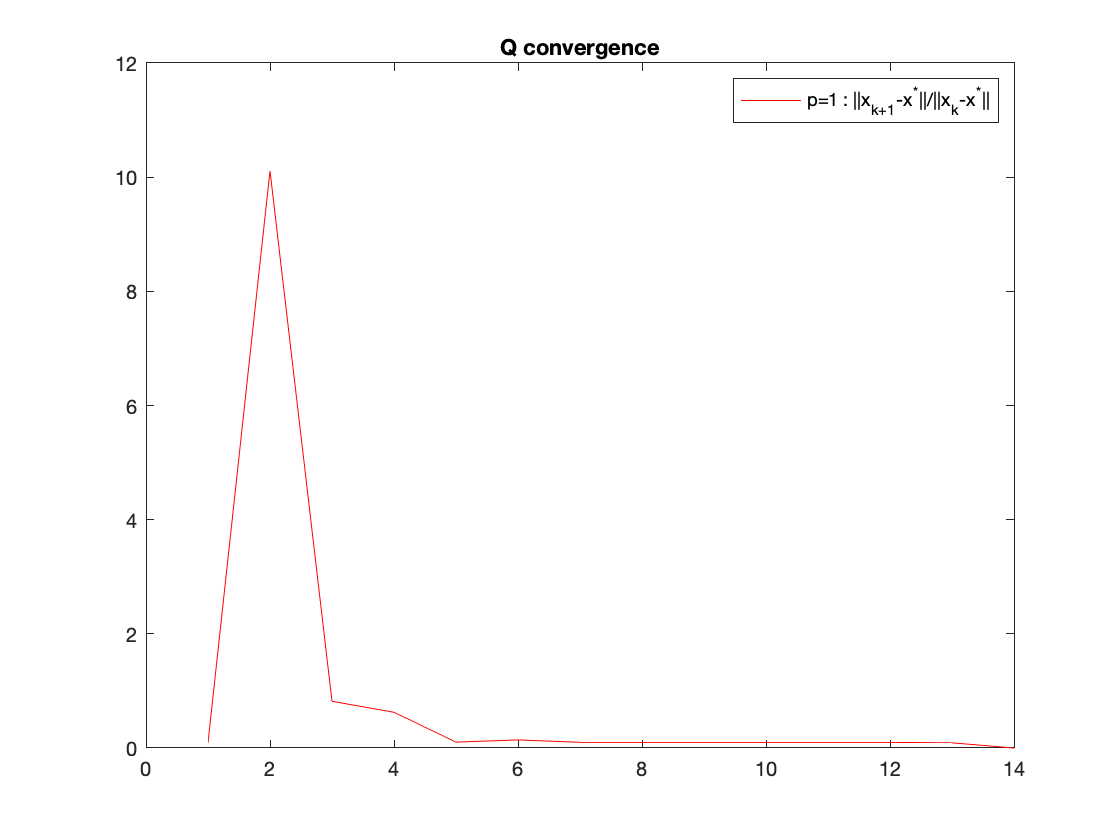

%Investigating convergence
conSteep = convergenceHistory(info, info.xs(:,end), F, 2); % using 2-norm

%Q-convergence rate
p = 1; 
% convergance rate
rs1 = conSteep.x(2:end)./(conSteep.x(1:end-1).^p); 
ps=1.4; rss = conSteep.x(2:end)./(conSteep.x(1:end-1).^ps); 
p=2; rs2 = conSteep.x(2:end)./(conSteep.x(1:end-1).^p); 
figure, plot(rs1, 'r'); hold on; legend('p=1')
legend('p=1 : ||x_{k+1}-x^*||/||x_{k}-x^*||')

saveas(gcf,'Artworks/6bCMLM-101010.png')

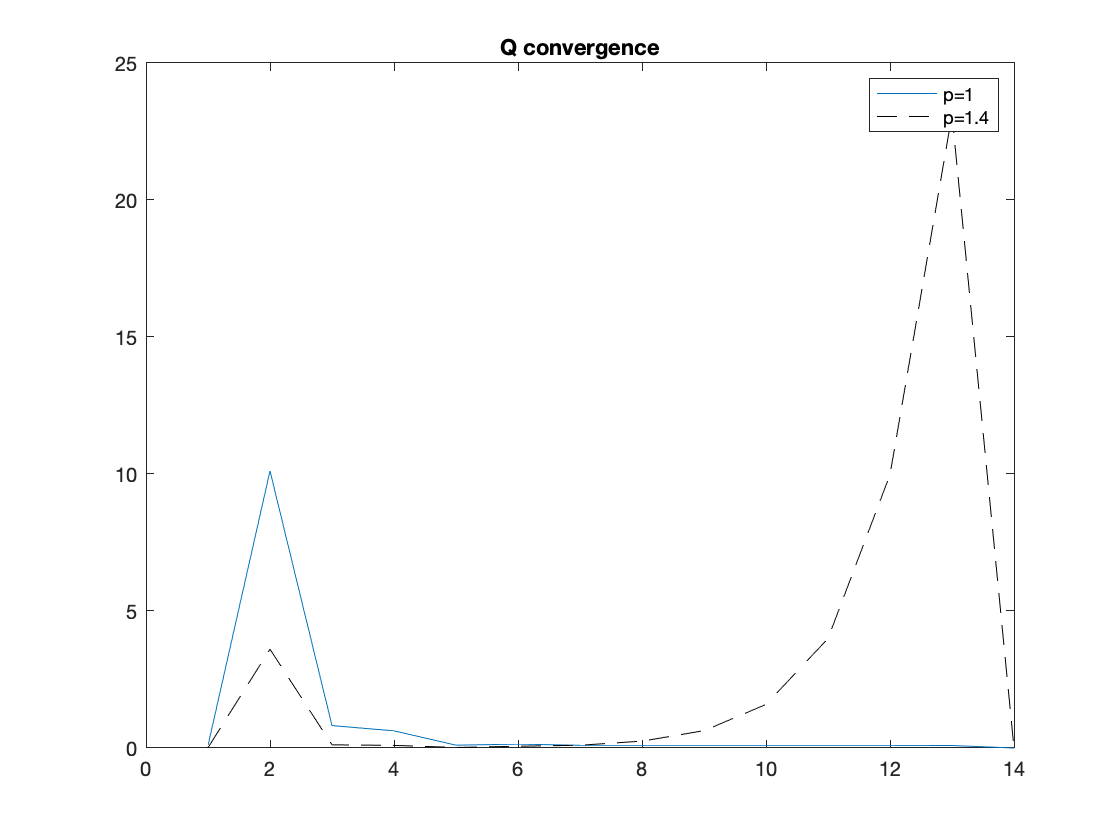

figure, plot(rs1); hold on; plot(rss,'k--'); title('Q convergence'); legend('p=1',['p=' num2str(ps)])

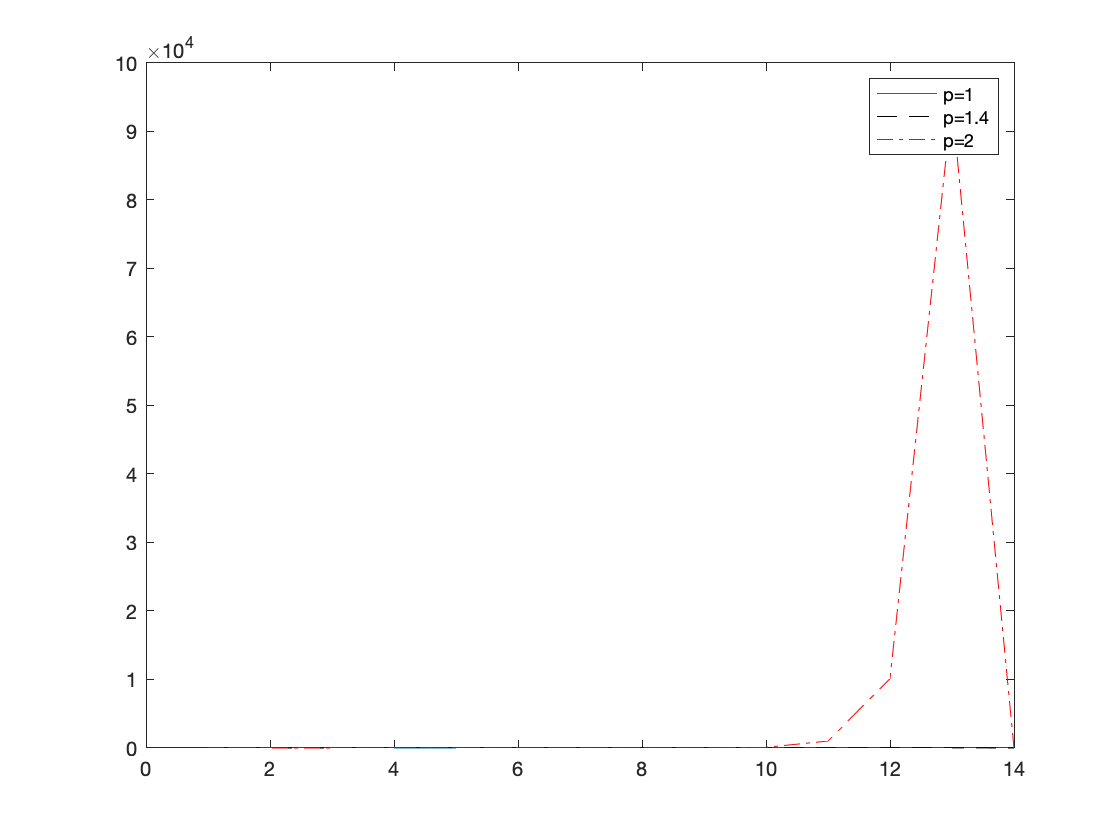

% saveas(gcf, 'un_conv_2', 'epsc')
figure, plot(rs1); hold on; plot(rss,'k--'); plot(rs2,'r-.'); legend('p=1',['p=' num2str(ps)],'p=2')

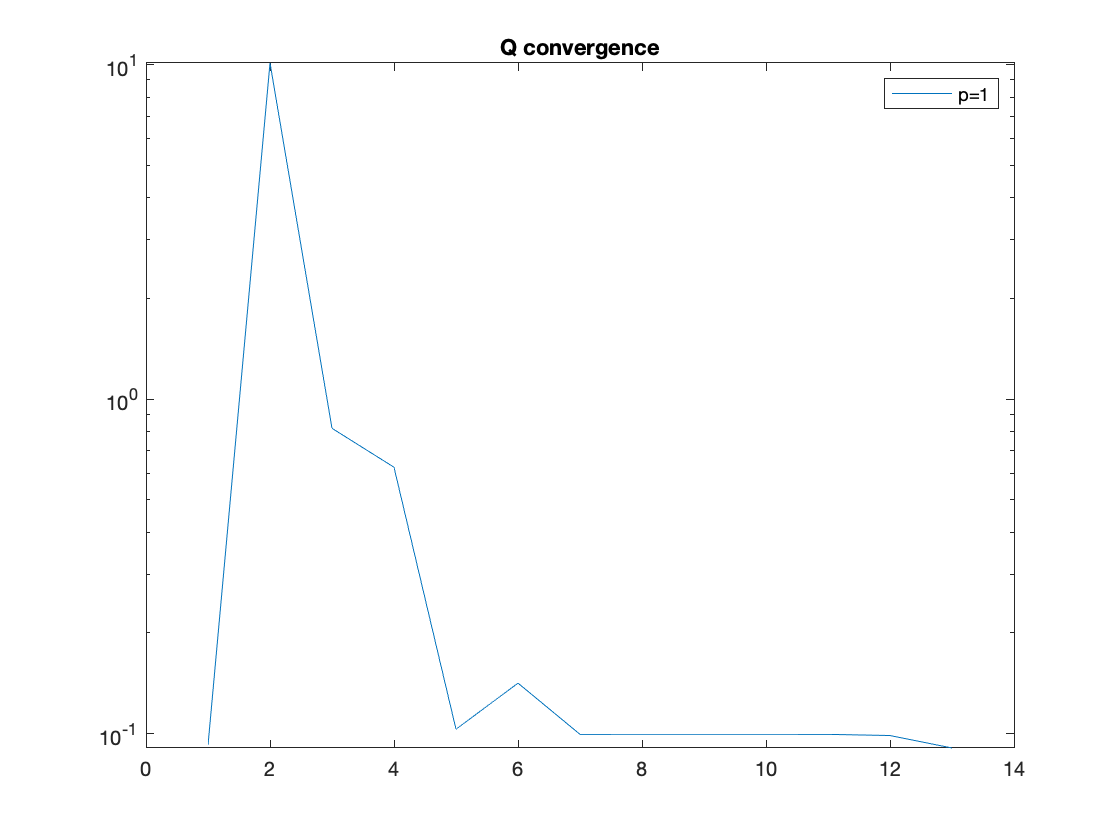

% saveas(gcf, 'FR2_Q2.png')
figure, semilogy(rs1); hold on; title('Q convergence'); legend('p=1')

$$f = {\mathrm{e}}^{-t\,x_{3}}\,\left(x_{2}\,t^{2}+x_{1}\right)$$

$$ans = \left(\begin{array}{ccc} 0 & 0 & -t\,{\mathrm{e}}^{-t\,x_{3}}\\ 0 & 0 & -t^{3}\,{\mathrm{e}}^{-t\,x_{3}}\\ -t\,{\mathrm{e}}^{-t\,x_{3}} & -t^{3}\,{\mathrm{e}}^{-t\,x_{3}} & t^{2}\,{\mathrm{e}}^{-t\,x_{3}}\,\left(x_{2}\,t^{2}+x_{1}\right) \end{array}\right)$$

sums = [0,0,0;0,0,0;0,0,0]

sums =      0     0     0
     0     0     0
     0     0     0


Hessians = [];
for i = 1:200
    Hessians(:,:,1,i) = [0, 0,exp(-xMin(3).*t(i)).*-((t(i))); 
    0, 0, exp(-xMin(3).*t(i)).*(-t(i).^3);
    exp(-xMin(3).*t(i)).*(-t(i)), exp(-xMin(3).*t(i)).*(-t(i).^3), t(i).^2.*exp(-xMin(3).*t(i)).*(xMin(1)+t(i).^2.*xMin(2))];
    sums = sums + ((xMin(1)+xMin(2).*t(i).^2).*exp(-xMin(3).*t(i))-y(i))'.*Hessians(:,:,1,i);
end

Hessians =      0     0     0
     0     0     0
     0     0     0


sums =      0     0     0
     0     0     0
     0     0     0


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


sums =                          0                         0        0.0153073786752038
                         0                         0      6.18464328686803e-06
        0.0153073786752038      6.18464328686803e-06      -0.00101401253505205


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


sums =                          0                         0       -0.0407844844546496
                         0                         0      -8.4466583710193e-05
       -0.0407844844546496      -8.4466583710193e-05        0.0068198156389591


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


sums =                          0                         0       -0.0615899109050025
                         0                         0     -0.000160120769434059
       -0.0615899109050025     -0.000160120769434059        0.0115515072211542


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0        -0.127319248781732
                         0                         0     -0.000585026971207823
        -0.127319248781732     -0.000585026971207823        0.0336834141187665


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0        -0.121832553695431
                         0                         0     -0.000529607208208897
        -0.121832553695431     -0.000529607208208897        0.0310789053235601


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0        0.0695099197025528
                         0                         0       0.00225348576109084
        0.0695099197025528       0.00225348576109084       -0.0930157984427988


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0       -0.0424603015146524
                         0                         0      3.67575614421173e-05
       -0.0424603015146524      3.67575614421173e-05       0.00388808849688739


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0         0.178217392345509
                         0                         0       0.00574302655749791
         0.178217392345509       0.00574302655749791        -0.246041894073734


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0         0.103045421137528
                         0                         0       0.00328291507835487
         0.103045421137528       0.00328291507835487        -0.136511728479324


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0      -0.00116567872939992
                         0                         0     -0.000927528086895622
      -0.00116567872939992     -0.000927528086895622        0.0558756315229223


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0        0.0770300621531962
                         0                         0       0.00289527826518402
        0.0770300621531962       0.00289527826518402        -0.124517277424016


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0         0.176640415456931
                         0                         0       0.00869064338252464
         0.176640415456931       0.00869064338252464          -0.4080743508468


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0         0.213505907332576
                         0                         0        0.0112078598677584
         0.213505907332576        0.0112078598677584        -0.536088741510681


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0        -0.037094691999011
                         0                         0      -0.00863718140654922
        -0.037094691999011      -0.00863718140654922         0.514314313645562


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0        -0.159685818766874
                         0                         0       -0.0197815478711412
        -0.159685818766874       -0.0197815478711412          1.12862431012496


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0        -0.314117613771488
                         0                         0       -0.0357546958305083
        -0.314117613771488       -0.0357546958305083          2.04566532469407


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0        -0.405785783170918
                         0                         0       -0.0464583047116721
        -0.405785783170918       -0.0464583047116721          2.68551455028425


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0        -0.546115903402189
                         0                         0       -0.0648283292888016
        -0.546115903402189       -0.0648283292888016          3.82835078406239


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0        -0.462774306124635
                         0                         0       -0.0526725487308574
        -0.462774306124635       -0.0526725487308574          3.04186472559705


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0        -0.266851175075028
                         0                         0        -0.021009003903265
        -0.266851175075028        -0.021009003903265         0.912927603291031


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0        -0.305773750002936
                         0                         0       -0.0279441239429438
        -0.305773750002936       -0.0279441239429438          1.39708368231117


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0         -0.19016861129885
                         0                         0      -0.00533746769374693
         -0.19016861129885      -0.00533746769374693        -0.240159371637555


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0       -0.0333388772636956
                         0                         0        0.0281820613301046
       -0.0333388772636956        0.0281820613301046         -2.75627581465896


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0       0.00569899880133817
                         0                         0        0.0372670103418808
       0.00569899880133817        0.0372670103418808         -3.46246571695533


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0       -0.0317537553324639
                         0                         0         0.027809482972925
       -0.0317537553324639         0.027809482972925         -2.70186450294801


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0         -0.11965956391791
                         0                         0       0.00380026033561313
         -0.11965956391791       0.00380026033561313         -0.70587049187372


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0        -0.324824772073151
                         0                         0       -0.0566286931737106
        -0.324824772073151       -0.0566286931737106          4.48282823694544


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0         -0.35887004387679
                         0                         0       -0.0674128625003651
         -0.35887004387679       -0.0674128625003651          5.43842218092676


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0        -0.309822877113542
                         0                         0       -0.0507471551705942
        -0.309822877113542       -0.0507471551705942          3.91564563007001


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0        -0.325522211581003
                         0                         0       -0.0564558599086421
        -0.325522211581003       -0.0564558599086421          4.45309801024207


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0        -0.264803027416207
                         0                         0       -0.0328802386940793
        -0.264803027416207       -0.0328802386940793          2.16785837069491


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0        -0.235883728009474
                         0                         0       -0.0209155458459212
        -0.235883728009474       -0.0209155458459212         0.974627429405856


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0       -0.0921050668044771
                         0                         0        0.0423454675839385
       -0.0921050668044771        0.0423454675839385         -5.51191651705411


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0        -0.186093013087754
                         0                         0      -0.00155244040968529
        -0.186093013087754      -0.00155244040968529        -0.887182920843763


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0        -0.186666212543143
                         0                         0      -0.00183613802655417
        -0.186666212543143      -0.00183613802655417         -0.85649363225482


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0        -0.122971827755254
                         0                         0        0.0315157157893006
        -0.122971827755254        0.0315157157893006         -4.55880274941411


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0        -0.168552020615715
                         0                         0       0.00630452050596082
        -0.168552020615715       0.00630452050596082         -1.68860786582369


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0       -0.0997549642691599
                         0                         0        0.0464420723311879
       -0.0997549642691599        0.0464420723311879         -6.37229315760793


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0        -0.383139632600137
                         0                         0        -0.127706289793573
        -0.383139632600137        -0.127706289793573          14.4456701193849


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0        -0.286479554281523
                         0                         0       -0.0652205443589495
        -0.286479554281523       -0.0652205443589495           6.7975614641508


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0        -0.190931267980662
                         0                         0     -0.000326559147768926
        -0.190931267980662     -0.000326559147768926         -1.33098145673383


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0        -0.172707228396962
                         0                         0        0.0126618828918346
        -0.172707228396962        0.0126618828918346         -2.99512074808397


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0        -0.211548599037275
                         0                         0       -0.0163546345956786
        -0.211548599037275       -0.0163546345956786         0.805892138093365


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0        -0.262698555181232
                         0                         0       -0.0563642566131836
        -0.262698555181232       -0.0563642566131836          6.16194118039067


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0        -0.510633076319535
                         0                         0        -0.259214651423441
        -0.510633076319535        -0.259214651423441          33.9011302452414


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0        -0.327796026211251
                         0                         0         -0.10290215506057
        -0.327796026211251         -0.10290215506057          12.0754396105838


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums =                          0                         0        -0.217523946051152
                         0                         0      -0.00448402417552865
        -0.217523946051152      -0.00448402417552865         -1.95046512710831


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.362675835535366
                         0                         0        -0.139603825542819
        -0.362675835535366        -0.139603825542819          17.6961400930072


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.561669812756036
                         0                         0          -0.3326432091167
        -0.561669812756036          -0.3326432091167          46.3223835070313


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.603087579856383
                         0                         0        -0.374478281059678
        -0.603087579856383        -0.374478281059678          52.6472543847368


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0          -0.4966701585748
                         0                         0        -0.262646069649503
          -0.4966701585748        -0.262646069649503          35.4159201032688


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.372331921788056
                         0                         0        -0.126806836389189
        -0.372331921788056        -0.126806836389189          14.0917901373145


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.290624745329244
                         0                         0        -0.034075659429899
        -0.290624745329244        -0.034075659429899        -0.734213476386859


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.180805628030472
                         0                         0        0.0953079605971584
        -0.180805628030472        0.0953079605971584         -21.7958752482207


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        0.0516562790810648
                         0                         0         0.379420894719994
        0.0516562790810648         0.379420894719994         -68.8704670571787


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0          -0.1517557271469
                         0                         0         0.121690008517767
          -0.1517557271469         0.121690008517767         -25.4178736999861


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       -0.0867105079367397
                         0                         0         0.207074485561806
       -0.0867105079367397         0.207074485561806         -40.0617934432562


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       -0.0859126873530215
                         0                         0         0.208158849469234
       -0.0859126873530215         0.208158849469234         -40.2509241446525


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.166365832878795
                         0                         0         0.095007201955195
        -0.166365832878795         0.095007201955195         -20.1859083401289


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       -0.0789560815369288
                         0                         0         0.222145447890688
       -0.0789560815369288         0.222145447890688         -43.1016074801379


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       -0.0741846278323918
                         0                         0         0.229318834112079
       -0.0741846278323918         0.229318834112079         -44.4154684213993


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        0.0606753443338683
                         0                         0         0.438768790631199
        0.0606753443338683         0.438768790631199         -83.3887542040872


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       -0.0444800165162839
                         0                         0         0.270142088390648
       -0.0444800165162839         0.270142088390648         -51.5195634596319


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.128294340286944
                         0                         0         0.131437118247622
        -0.128294340286944         0.131437118247622         -24.9004235564666


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       -0.0814038455139165
                         0                         0         0.211480487017518
       -0.0814038455139165         0.211480487017518         -40.4954777507959


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.165936794383943
                         0                         0        0.0627062539313493
        -0.165936794383943        0.0627062539313493         -11.0747265184572


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.152037682707348
                         0                         0        0.0879149556575631
        -0.152037682707348        0.0879149556575631         -16.1335396163959


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.187782689564067
                         0                         0        0.0211348595163661
        -0.187782689564067        0.0211348595163661         -2.53702943291325


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       -0.0863556500682347
                         0                         0         0.216238674082527
       -0.0863556500682347         0.216238674082527         -42.8310870574208


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       -0.0464944370894036
                         0                         0         0.295153830203341
       -0.0464944370894036         0.295153830203341         -59.3600422798838


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       -0.0810548427516674
                         0                         0         0.224764090573141
       -0.0810548427516674         0.224764090573141          -44.410729090838


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.134599969658162
                         0                         0         0.112614220465511
        -0.134599969658162         0.112614220465511         -20.2640797210738


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.167843299721202
                         0                         0        0.0410387730148139
        -0.167843299721202        0.0410387730148139         -4.64376450743715


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        0.0236020132138804
                         0                         0         0.464605666227616
        0.0236020132138804         0.464605666227616         -98.3220116857268


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        0.0192165748257135
                         0                         0         0.454639012483139
        0.0192165748257135         0.454639012483139         -96.0885295587077


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       0.00307200809565396
                         0                         0         0.416962785142284
       0.00307200809565396         0.416962785142284         -87.5350252632605


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       -0.0125201756757456
                         0                         0         0.379611785892517
       -0.0125201756757456         0.379611785892517         -78.9458504755835


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        0.0953578503184676
                         0                         0         0.644788891581279
        0.0953578503184676         0.644788891581279         -140.703179682764


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.027298157539497
                         0                         0         0.335505330038265
        -0.027298157539497         0.335505330038265         -67.7666715459472


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        0.0469129478673569
                         0                         0         0.527399908297951
        0.0469129478673569         0.527399908297951         -113.583020652799


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0      -0.00247066637872088
                         0                         0         0.396491742112849
      -0.00247066637872088         0.396491742112849         -81.9435135804865


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.021950922151638
                         0                         0          0.34356974930778
        -0.021950922151638          0.34356974930778         -68.9973406299395


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        0.0185277106041704
                         0                         0         0.456236520775072
        0.0185277106041704         0.456236520775072         -96.8894790039649


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       -0.0406495253020178
                         0                         0         0.287531861173925
       -0.0406495253020178         0.287531861173925         -54.6290707216357


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       -0.0176105143646307
                         0                         0         0.354785457405383
       -0.0176105143646307         0.354785457405383         -71.6735614547737


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       -0.0241799764428928
                         0                         0         0.335154542416033
       -0.0241799764428928         0.335154542416033         -66.6407166891781


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.104860461940835
                         0                         0        0.0884251791236225
        -0.104860461940835        0.0884251791236225         -2.66102504444127


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       -0.0967998595878579
                         0                         0         0.113645271392586
       -0.0967998595878579         0.113645271392586         -9.27498180705313


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       -0.0685590450759655
                         0                         0         0.204025005944219
       -0.0685590450759655         0.204025005944219         -33.2426271400254


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       -0.0382751258030568
                         0                         0         0.303133511733693
       -0.0382751258030568         0.303133511733693         -59.8163417674482


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       -0.0690546553120972
                         0                         0         0.200152159196388
       -0.0690546553120972         0.200152159196388         -31.9014802760698


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       -0.0723822921376665
                         0                         0         0.188772600865389
       -0.0723822921376665         0.188772600865389          -28.783398958825


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       -0.0456279775205961
                         0                         0         0.282264408495718
       -0.0456279775205961         0.282264408495718         -54.6757434664547


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       -0.0237906606712034
                         0                         0         0.360223866764442
       -0.0237906606712034         0.360223866764442          -76.495710070085


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       -0.0436475851493273
                         0                         0         0.287818122095341
       -0.0436475851493273         0.287818122095341         -56.0171985599119


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.101048028528832
                         0                         0        0.0740851411360645
        -0.101048028528832        0.0740851411360645          5.06161574317158


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       -0.0921761359163171
                         0                         0         0.107811819792121
       -0.0921761359163171         0.107811819792121         -4.67573578346009


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       -0.0817961969866084
                         0                         0         0.148089159649568
       -0.0817961969866084         0.148089159649568         -16.4228637358996


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       -0.0251833053361647
                         0                         0         0.372270549439118
       -0.0251833053361647         0.372270549439118           -82.46641574763


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       -0.0871504486740971
                         0                         0         0.121904575497319
       -0.0871504486740971         0.121904575497319         -7.97207755927568


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.102756692593241
                         0                         0        0.0575832526138833
        -0.102756692593241        0.0575832526138833          11.3555254637133


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       -0.0895072087862362
                         0                         0         0.113277858114987
       -0.0895072087862362         0.113277858114987         -5.54382467555004


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       -0.0954260794491907
                         0                         0        0.0879074689376289
       -0.0954260794491907        0.0879074689376289          2.22897362357772


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       -0.0289002018291656
                         0                         0         0.378624932572665
       -0.0289002018291656         0.378624932572665         -87.6949187488297


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.043275117942898
                         0                         0         0.314592832310995
        -0.043275117942898         0.314592832310995         -67.7001457670496


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.121001618823364
                         0                         0       -0.0382608689159103
        -0.121001618823364       -0.0382608689159103          43.5216558449006


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.100588729329619
                         0                         0         0.056163886747388
        -0.100588729329619         0.056163886747388          13.4802608119945


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.144757576548731
                         0                         0        -0.151986587821929
        -0.144757576548731        -0.151986587821929          80.3167683716933


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.108551742674853
                         0                         0        0.0218116545479243
        -0.108551742674853        0.0218116545479243          23.9987145567431


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       -0.0991905029633505
                         0                         0        0.0675765596802929
       -0.0991905029633505        0.0675765596802929          9.03411218031681


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.110608734007585
                         0                         0          0.01073596486864
        -0.110608734007585          0.01073596486864          27.7877987669188


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.138570075243952
                         0                         0        -0.130976442179255
        -0.138570075243952        -0.130976442179255          74.9611811175307


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       -0.0926563688370909
                         0                         0         0.105895199288064
       -0.0926563688370909         0.105895199288064         -4.58687742566893


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       -0.0867705379917292
                         0                         0         0.136800381547631
       -0.0867705379917292         0.136800381547631          -15.056765718583


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.100381376808304
                         0                         0        0.0640735945072237
        -0.100381376808304        0.0640735945072237           9.7955452469469


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.118397910891648
                         0                         0       -0.0338756421789138
        -0.118397910891648       -0.0338756421789138           43.555591822749


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.124174160357679
                         0                         0       -0.0658227461168915
        -0.124174160357679       -0.0658227461168915          54.6609247030517


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       -0.0981522548841351
                         0                         0        0.0805691174476128
       -0.0981522548841351        0.0805691174476128          3.34121921735687


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       -0.0589798892232282
                         0                         0         0.304692698215413
       -0.0589798892232282         0.304692698215413         -75.8891050302198


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       -0.0599430241441011
                         0                         0         0.299089145634187
       -0.0599430241441011         0.299089145634187          -73.891663707743


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       -0.0528672044015351
                         0                         0         0.340945493443953
       -0.0528672044015351         0.340945493443953         -88.9351718960365


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       -0.0480212868545816
                         0                         0         0.370086833013704
       -0.0480212868545816         0.370086833013704         -99.4947244879142


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       -0.0803765125459502
                         0                         0         0.172313156799582
       -0.0803765125459502         0.172313156799582         -27.2470023261075


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       -0.0791514312652463
                         0                         0         0.179923813004063
       -0.0791514312652463         0.179923813004063         -30.0496554676303


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       -0.0892115869657314
                         0                         0         0.116414332811106
       -0.0892115869657314         0.116414332811106         -6.47476234822662


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0       -0.0977498016114988
                         0                         0        0.0616469498798861
       -0.0977498016114988        0.0616469498798861          14.0165545799591


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.101434866335524
                         0                         0        0.0376328456163371
        -0.101434866335524        0.0376328456163371          23.0722995687197


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.148863020036623
                         0                         0        -0.276324022236015
        -0.148863020036623        -0.276324022236015          142.391766756746


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.161354369145263
                         0                         0        -0.360309190496162
        -0.161354369145263        -0.360309190496162          174.558092584702


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0         -0.15106467277075
                         0                         0        -0.290050007655618
         -0.15106467277075        -0.290050007655618          147.441575453836


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.150330199877556
                         0                         0        -0.284957494104907
        -0.150330199877556        -0.284957494104907          145.461098674683


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.158571131662806
                         0                         0        -0.342972188855525
        -0.158571131662806        -0.342972188855525          168.194137423391


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.164157345492621
                         0                         0        -0.382896245898767
        -0.164157345492621        -0.382896245898767          183.956147694182


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.179304990520799
                         0                         0        -0.492788870479345
        -0.179304990520799        -0.492788870479345          227.665949877883


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.189076396337696
                         0                         0        -0.564740132725432
        -0.189076396337696        -0.564740132725432          256.496857801244


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.197113700051934
                         0                         0        -0.624802442060466
        -0.197113700051934        -0.624802442060466          280.741072954592


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.200139130318322
                         0                         0        -0.647745014488371
        -0.200139130318322        -0.647745014488371           290.06956288368


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.194099854000129
                         0                         0        -0.601276701787715
        -0.194099854000129        -0.601276701787715          271.038347153054


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.195069875063335
                         0                         0        -0.608848945705673
        -0.195069875063335        -0.608848945705673          274.161924045014


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.196637892639063
                         0                         0        -0.621266064256932
        -0.196637892639063        -0.621266064256932          279.320672008997


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.206076329724789
                         0                         0         -0.69708054074038
        -0.206076329724789         -0.69708054074038          311.041879376455


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.196786759949957
                         0                         0        -0.621399670079654
        -0.196786759949957        -0.621399670079654          279.153218223822


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.195090501322707
                         0                         0        -0.607385158256767
        -0.195090501322707        -0.607385158256767          273.206743923766


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.190300864177595
                         0                         0        -0.567257720731033
        -0.190300864177595        -0.567257720731033          256.061901249504


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.188848436829962
                         0                         0        -0.554919735333098
        -0.188848436829962        -0.554919735333098          250.753958649813


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.182202450060168
                         0                         0        -0.497682451836239
        -0.182202450060168        -0.497682451836239          225.960875827247


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.169701314684808
                         0                         0        -0.388538931490326
        -0.169701314684808        -0.388538931490326          178.361751560041


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.173786281297092
                         0                         0        -0.424690385716424
        -0.173786281297092        -0.424690385716424          194.234658449149


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.169886796401841
                         0                         0        -0.389712495598716
        -0.169886796401841        -0.389712495598716          178.773769376435


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.165043834138494
                         0                         0        -0.345686677695003
        -0.165043834138494        -0.345686677695003          159.183555809847


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.165537544054608
                         0                         0        -0.350234877911078
        -0.165537544054608        -0.350234877911078          161.220800389915


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.152013683663529
                         0                         0        -0.223993512096889
        -0.152013683663529        -0.223993512096889          104.301655868486


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.159299399847583
                         0                         0        -0.292901400343151
        -0.159299399847583        -0.292901400343151           135.57398081053


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.162983554253217
                         0                         0        -0.328202895107033
        -0.162983554253217        -0.328202895107033          151.699012582975


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.162823621090821
                         0                         0         -0.32665045179436
        -0.162823621090821         -0.32665045179436          150.985303164454


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.162993448416823
                         0                         0         -0.32832027540713
        -0.162993448416823         -0.32832027540713          151.757906601357


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.164687408161008
                         0                         0        -0.345190319591637
        -0.164687408161008        -0.345190319591637           159.61324702683


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.167851862880735
                         0                         0        -0.377107674253697
        -0.167851862880735        -0.377107674253697          174.569439520039


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.163391078382669
                         0                         0        -0.331543938834651
        -0.163391078382669        -0.331543938834651          153.084127090124


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0         -0.16400450843243
                         0                         0        -0.337888752056085
         -0.16400450843243        -0.337888752056085          156.094722751067


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.168613880725206
                         0                         0         -0.38616209432564
        -0.168613880725206         -0.38616209432564          179.142839563271


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.159944134191256
                         0                         0        -0.294233576141972
        -0.159944134191256        -0.294233576141972          134.980072100181


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.155589947257394
                         0                         0         -0.24749277963853
        -0.155589947257394         -0.24749277963853          112.387601292934


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.148569969099448
                         0                         0        -0.171208107014665
        -0.148569969099448        -0.171208107014665          75.2896128522072


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.148911325713409
                         0                         0        -0.174962934949353
        -0.148911325713409        -0.174962934949353            77.12671208874


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.140402448999783
                         0                         0       -0.0802297285270137
        -0.140402448999783       -0.0802297285270137          30.4974488445148


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.136553762775182
                         0                         0        -0.036862738756903
        -0.136553762775182        -0.036862738756903          9.02340876327638


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.144422219777049
                         0                         0         -0.12658949532191
        -0.144422219777049         -0.12658949532191          53.7184379856972


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.149794922739005
                         0                         0         -0.18858783649367
        -0.149794922739005         -0.18858783649367          84.7844059651138


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.147644756483763
                         0                         0        -0.163481478663717
        -0.147644756483763        -0.163481478663717          72.1300202977281


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.148248856996376
                         0                         0        -0.170618471402008
        -0.148248856996376        -0.170618471402008          75.7483678495568


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.148932387600415
                         0                         0        -0.178788596152355
        -0.148932387600415        -0.178788596152355          79.9146310074912


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0         -0.14522353577335
                         0                         0        -0.133940344307306
         -0.14522353577335        -0.133940344307306          56.9122921780498


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0         -0.13946406849195
                         0                         0       -0.0634881309140414
         -0.13946406849195       -0.0634881309140414          20.5697559017469


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.138283135130257
                         0                         0       -0.0488759406352708
        -0.138283135130257       -0.0488759406352708          12.9889420487797


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.137993093021028
                         0                         0       -0.0452459941690832
        -0.137993093021028       -0.0452459941690832          11.0950002611984


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.131074811078591
                         0                         0         0.042324665147451
        -0.131074811078591         0.042324665147451         -34.8541034956571


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.131216478023761
                         0                         0        0.0405111450885471
        -0.131216478023761        0.0405111450885471         -33.8971758765592


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.132634627566062
                         0                         0        0.0221524452638544
        -0.132634627566062        0.0221524452638544         -24.1557309185334


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.134410234671354
                         0                         0      -0.00109127896996727
        -0.134410234671354      -0.00109127896996727         -11.7535377424648


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.136506901326553
                         0                         0       -0.0288436675625637
        -0.136506901326553       -0.0288436675625637          3.13634209135521


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.136380180768386
                         0                         0       -0.0271477541184671
        -0.136380180768386       -0.0271477541184671          2.22142986641663


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.138652065437706
                         0                         0       -0.0578876427842551
        -0.138652065437706       -0.0578876427842551          18.8958207478911


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.143295075535318
                         0                         0        -0.121398665178543
        -0.143295075535318        -0.121398665178543          53.5340665359227


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.146418304789237
                         0                         0        -0.164586472038119
        -0.146418304789237        -0.164586472038119          77.2158458280505


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.145489556468568
                         0                         0         -0.15160458697385
        -0.145489556468568         -0.15160458697385          70.0589488954309


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.143140739796902
                         0                         0        -0.118419255212934
        -0.143140739796902        -0.118419255212934          51.6658648249227


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.140632482701845
                         0                         0       -0.0826012349537798
        -0.140632482701845       -0.0826012349537798          31.7077712279374


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.135914937892988
                         0                         0       -0.0145159166568987
        -0.135914937892988       -0.0145159166568987         -6.43110214478193


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.138134676250613
                         0                         0        -0.046891888863764
        -0.138134676250613        -0.046891888863764          11.8003839002602


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.135558733193032
                         0                         0        -0.008923967373444
        -0.135558733193032        -0.008923967373444         -9.69221900538042


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.135457587167175
                         0                         0       -0.0074174813363513
        -0.135457587167175       -0.0074174813363513         -10.5494511448182


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.136346706689296
                         0                         0       -0.0207984820502728
        -0.136346706689296       -0.0207984820502728          -2.8957518744781


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.137132557670235
                         0                         0         -0.03274819544887
        -0.137132557670235         -0.03274819544887          3.97458760945597


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.135683726598988
                         0                         0       -0.0104894438075743
        -0.135683726598988       -0.0104894438075743         -8.88858152768813


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.134672104868165
                         0                         0       0.00521216389375879
        -0.134672104868165       0.00521216389375879         -18.0088252390166


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.137535429647234
                         0                         0       -0.0396847917794417
        -0.137535429647234       -0.0396847917794417          8.20214820725382


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.136024053949617
                         0                         0       -0.0157452052641989
        -0.136024053949617       -0.0157452052641989         -5.84459814530267


Hessians = Hessians(:,:,1,1) =

     0     0     0
     0     0     0
     0     0     0


Hessians(:,:,1,2) =

                         0                         0       -0.0193131573469946
                         0                         0     -7.80309884982485e-06
       -0.0193131573469946     -7.80309884982485e-06       0.00127936886235189


Hessians(:,:,1,3) =

                         0                         0       -0.0371133056476223
                         0                         0     -5.99795854005663e-05
       -0.0371133056476223     -5.99795854005663e-05       0.00518326978620706


Hessians(:,:,1,4) =

                         0                         0       -0.0534893427061076
                         0                         0     -0.000194501789088142
       -0.0534893427061076     -0.000194501789088142        0.0121648586835548


Hessians(:,:,1,5) =

                         0                         0       -0.0685255234406682
                         0   

sums = 3×3
                         0                         0        -0.134854715426666
                         0                         0       0.00296421110302122
        -0.134854715426666       0.00296421110302122         -16.8777904549629


% Checking Hessian
app_hessian = F.J(xMin)'*F.J(xMin) + sums

app_hessian = 3×3
          13.0197261811708          1.58317085952482         -186.175446834431
          1.58317085952482           1.2013689360394         -226.069458779353
         -186.175446834431         -226.069458779353          50380.2891133954


rate_conv = norm(inv(F.J(xMin)'*F.J(xMin))*sums)

rate_conv =           16.8787730049459


Hmin =      0     0     0
     0     0     0
     0     0     0
